# Retinal mm per degree

It is sometimes necessary to convert measurements made along the retina from one set of units (degrees of visual angle) to another (millimeters). While there are rules-of-thumb for this conversion (e.g., 0.3 mm / degree), the precise value is complicated to obtain. This is because of individual varation in the ellipsoidal dimensions of the retina, as well as in the optics and accommodative state of the eye.

Drasdo & Fowler calculated this conversion as a function of position on the retina for an emmetropic eye:

- Drasdo N, Fowler CW. Non-linear projection of the retinal image in a wide-angle schematic eye. Br J Ophthalmol. 1974;58(8):709

Here I demonstrate how to calculate this value for different positions on the retina, and for eyes of different sizes and optics. We then examine the source of diffrences in the current model from the values reported by Drasdo & Fowler

## Basic calculation

The unit conversion is calculated for a particular eye under study. We first define a model eye structure, accommodated at infinity:

modelEye = modelEyeParameters('accommodation',0);

We can obtain the mm/deg of field angle for a point on the longitudinal axis with this function:

mmPerDeg = calcMmRetinaPerDeg(modelEye)

mmPerDeg = 0.2790

This value is reasonably close to that reported by Drasdo & Fowler on the optical axis for their model of an emmetropic eye that assumed a spherical retina.

## Visual degrees at the fovea

To be a bit more precise, we can define angle with respect to the approximate incident nodal point of the eye, and the field location as corresponding to the fovea:

fieldAngularPosition = eye.landmarks.fovea.degField(1:2);
rayOriginDistance = 1500;
angleReferenceCoord = eye.landmarks.incidentNode.coords;

We now call the function with these optional inputs:

mmPerDeg = calcMmRetinaPerDeg(eye,fieldAngularPosition,rayOriginDistance,angleReferenceCoord)

mmPerDeg = 0.2797

As can be seen, there is a small difference in the unit relationship depending upon the position in the visual field that we choose to interogate.

## Unit conversion as a function of field position

We can repeat the calculation, now for positions along the horizontal meridian, relative to the fovea, and plot the resulting function:

horizontalOffset = -40:5:40;
for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(modelEye,thisLocation,rayOriginDistance,angleReferenceCoord);
end
plot(horizontalOffset,mmPerDeg,'-k')
ylabel('mm/deg');
xlabel('horizontal field location relative to fovea [deg]');
xlim([-40 40])

## Comparison to Drasdo & Fowler

One of the "species" of model eye available in the software is Drasdo & Fowler 1974. We can examine the behavior of this model eye.

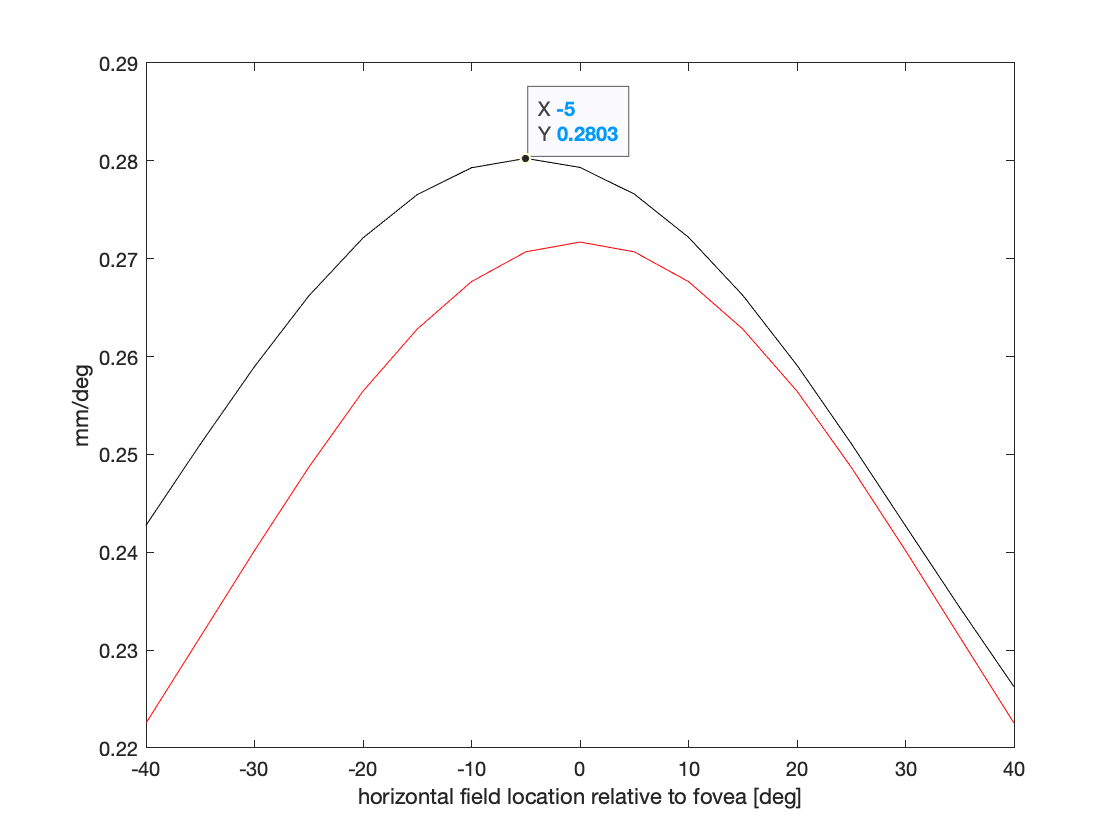

modelEye = modelEyeParameters('species','Drasdo');
horizontalOffset = -40:5:40;
for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii), 0];
    mmPerDeg(ii) = calcMmRetinaPerDeg(modelEye,thisLocation);
end
hold on
plot(horizontalOffset,mmPerDeg,'-r')

Using [https://automeris.io/WebPlotDigitizer/,](https://automeris.io/WebPlotDigitizer/,) I extracted the values for the  mm/deg relationship in the horizontal ("radial") direction from Figure 4, Drasdo & Fowler, 1974.

dfData = [0.14344384771044716, 0.27432995500303115
8.285589870132085, 0.27424798709005377
15.912448022951018, 0.2726611395247569
28.606801629112276, 0.2659897198575808
35.45325694379222, 0.26038388305911087
42.54348141633724, 0.2522588136852262
47.85261144647752, 0.24415167479230532
53.65995269768356, 0.23352274182668914
61.48148464382381, 0.2178399747265602
69.7990932299627, 0.1991320793381091
77.34697188329818, 0.1789218657946192
83.8664093784954, 0.1562052271621172
88.11934869662483, 0.13904831837703538
93.88826748862272, 0.11935936953013604
99.93297415449246, 0.1047012013422246
];